% startup



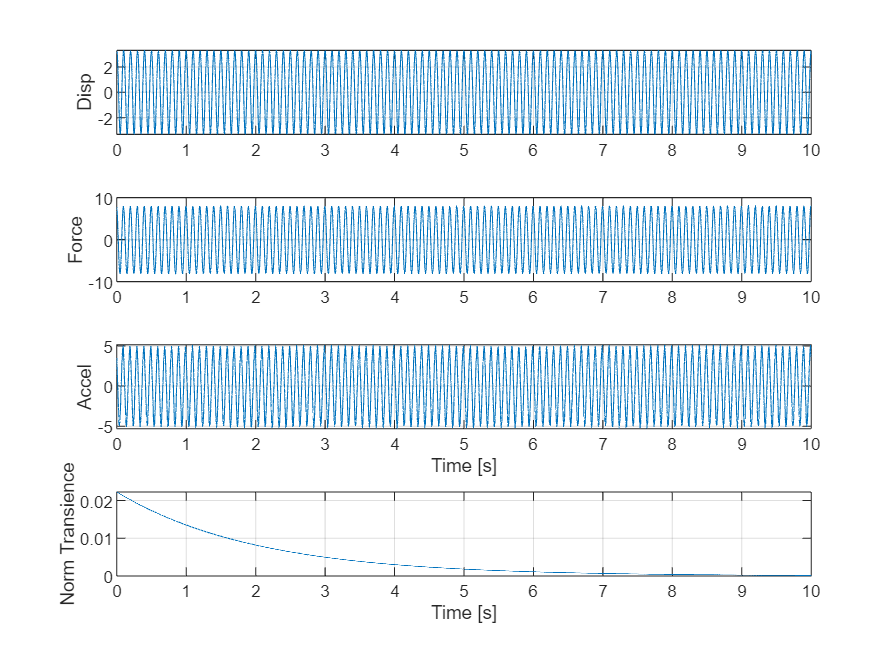

figure;
subplot(4,1,1); plot(t, disp_signal); ylabel('Disp'); grid on;
subplot(4,1,2); plot(t, force_signal); ylabel('Force'); grid on;
subplot(4,1,3); plot(t, acc_signal); ylabel('Accel'); xlabel('Time [s]'); grid on;
subplot(4,1,4); plot(t, disp_transience); ylabel('Norm Transience'); xlabel('Time [s]'); grid on;

addpath("funcs")

w0 = 10

w0 = 10

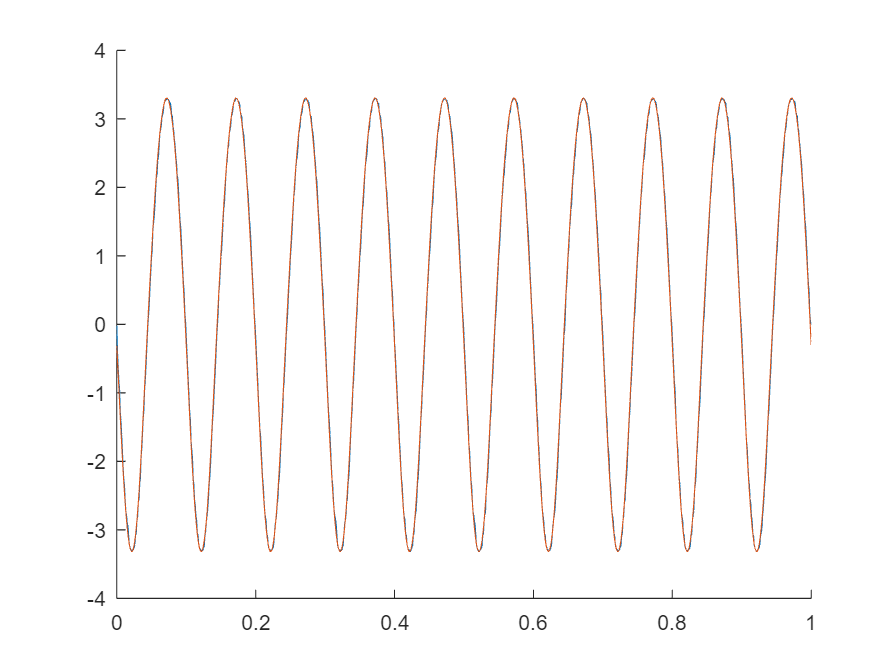

[t_trim, x_trim] = f_get_last_n_periods(t, disp_signal, 10);

t_lin = t_trim - t_trim(1);
x_trim(1) = 0;
x_trim(end) = 0;
[a_vec, b_vec] = f_get_fft_components(t_lin, x_trim, 2*pi*w0, k_harmonics)
[t_rec, x_rec] = f_get_reconstructed_wave(a_vec, b_vec, t_lin, 2*pi*w0);

figure;
hold on;
plot(t_lin, x_trim)
plot(t_lin, x_rec)

ans = 3.9333

norm([a_vec, b_vec])

ans = 3.2817

open_loop_freq_sweep = [frequencies; amplitudes]

open_loop_freq_sweep =   155.0000  155.2000  155.4000  155.6000  155.8000  156.0000  156.2000  156.4000  156.6000  156.8000  157.0000  157.2000  157.4000  157.6000  157.8000  158.0000  158.2000  158.4000  158.6000  158.8000  159.0000  159.2000  159.4000  159.6000  159.8000  160.0000  160.2000  160.4000  160.6000  160.8000  161.0000  161.2000  161.4000  161.6000  161.8000  162.0000  162.2000  162.4000  162.6000  162.8000  163.0000  163.2000  163.4000  163.6000  163.8000  164.0000  164.2000  164.4000  164.6000  164.8000
    0.2504    0.2529    0.2656    0.2779    0.2895    0.3050    0.3200    0.3405    0.3637    0.4023    0.4350    0.4747    0.5282    0.6427    0.5441    0.5106    0.4788    0.4490    0.4387    0.4262    0.4205    0.4744    0.5445    0.5230    0.5730    0.6862    1.0468    1.2272    2.4099    2.7221    2.3893    2.0874    1.8143    1.5826    1.3971    1.2510    1.1245    1.0143    0.9146    0.8301    0.7549    0.6973    0.6448    0.6003    0.5575    0.5242    0.4974    0.

test = struct with fields:
    open_loop_freq_sweep: [2×76 double]


test = load("saves\OL_blade_16_07_2025\freq_sweep_155_170_hz.mat", "open_loop_freq_sweep")

test = struct with fields:
    open_loop_freq_sweep: [2×76 double]


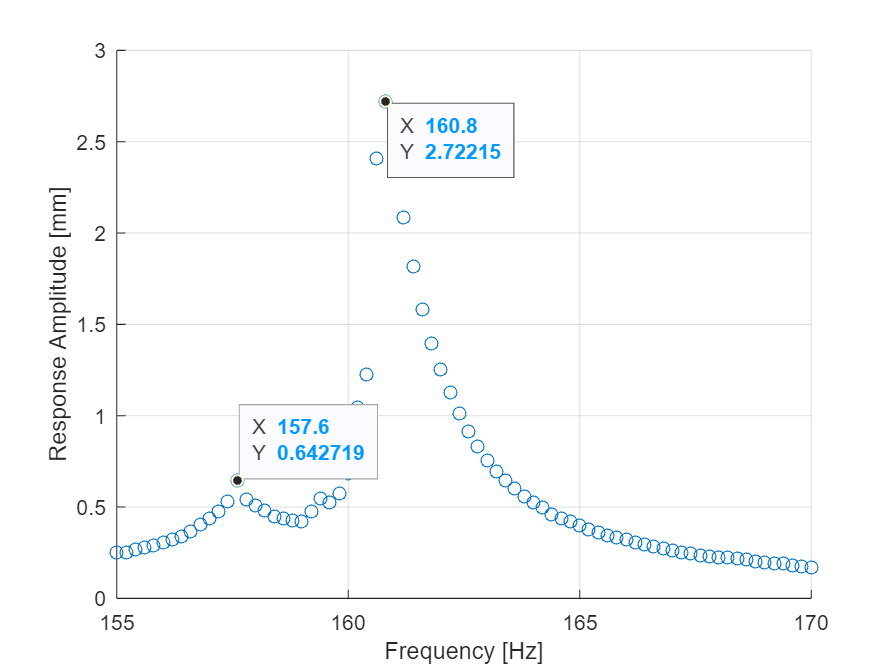

frequencies = test.open_loop_freq_sweep(1, :);
amplitudes = test.open_loop_freq_sweep(2, :);

figure;
scatter(frequencies, amplitudes)
xlabel("Frequency [Hz]");
ylabel("Response Amplitude [mm]")
grid on;

% save("saves\OL_blade_16_07_2025\freq_sweep_155_170_hz_amp_12.mat", "data")

test = load("saves\OL_blade_16_07_2025\freq_sweep_155_170_hz.mat", "open_loop_freq_sweep")

test = struct with fields:
    open_loop_freq_sweep: [2×76 double]


test12 = load("saves\OL_blade_16_07_2025\freq_sweep_155_170_hz_amp_12.mat", "data")

test12 = struct with fields:
    data: [1×1 struct]


frequencies = test.open_loop_freq_sweep(1, :);
amplitudes = test.open_loop_freq_sweep(2, :);

frequencies12 = test12.data(:, 1);
amplitudes12 = test12.data(:, 2);

Index in position 2 exceeds array bounds. Index must not exceed 1.


figure;
hold on;

scatter3(frequencies, 10, amplitudes)
scatter3(frequencies12, 10, amplitudes12)

xlabel("Frequency [Hz]");
ylabel("Response Amplitude [mm]")

temp = [31, 43, 53]

temp =     31    43    53


save("freq_sweep_155_170_hz.mat", "temp")
test = load("freq_sweep_155_170_hz.mat").temp

test =     31    43    53
